% Author: Gerardo Parra
clear

%% parameters for running batch script
% parameters for loading data
task      = 'tss';
beapp_tag = '_25hzLP_32hzNF';
file_tag  = [beapp_tag '_2023-01-13_gp']; % _rise-decay_avg
% file_tag = ['_HAPPE_V3_2023-01-19_yb_noexclusion_200msbl'];

data_path = fullfile( 'X:','Groups','SPA','01_Data_Raw_Summary_Processed', ...
                      'EEG','Participant_Data','03_Processed_Data' );

% parameters for processing
method    = 'conds_peak';
rois      = {'C3'};
groups    = {'TD','ASD'};
erps      = {'P50','P100','N140','P300','P4','P100_N140_dist','N140_P300_dist','P4_N140_dist'};  % components to calculate/plot
exclude   = {};
erps      = {'P100','P100_N140_dist','N140_P300_dist','P300','P4'};
%erps      = {'P100','N140','P300'};
%'VariableNames',{ 'P100'      'N250'        'N1c'     'P2'      'N1c_P2_dist' 'P100_N250_dist'
% erp_times = [55 103],[159 235],[156 204],[239 355], [156 204; 239 355], [55 103], [159 235]};
% erps = {'P100','N250'};%,'N1c','P2'};
% erp_times = [79 197];% 180 297 ]
%erps = {'N1c','P2'};
%erp_times = [180 297]
erp_times = [75 175 275 300 400];
%erp_times = [75 175 300];
%erps  = {'P50','P100','P300'};
% parameters for plots
save_figs  = false;
norm_data  = false;
cond_names = {'Index','Middle','Both'};
colors = {'#4444c9','#32a852','#e69a0e'};
colors = colors(1:2);
  

%% load batch information
task_path = get_task_path(task);
task_path_batch = fullfile(data_path,task_path,'erp',['erp' file_tag '.mat']);
load(task_path_batch,'batch');
if norm_data, method = [method '_norm']; end
batch.method = method;
% get save path
save_path = fullfile(data_path,task_path,'figures','erp_indiv');
if ~exist(save_path,'dir'), mkdir(save_path); end

% calculate or load group averages
calc_si = 1;
[data,batch] = calc_si_by_indiv(batch,exclude,erps,calc_si);

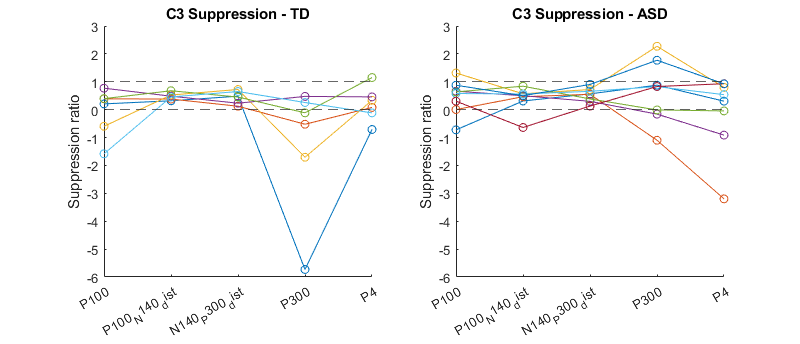

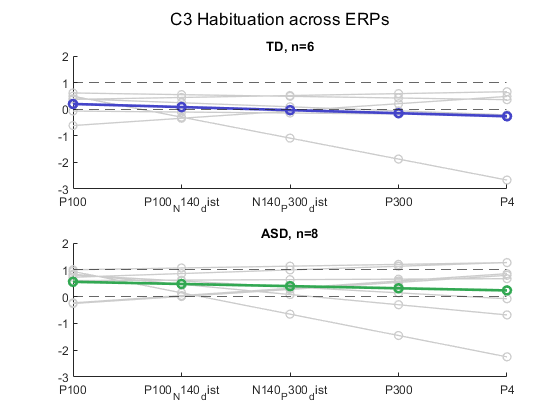

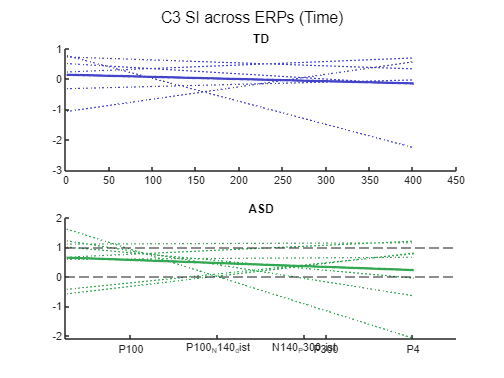

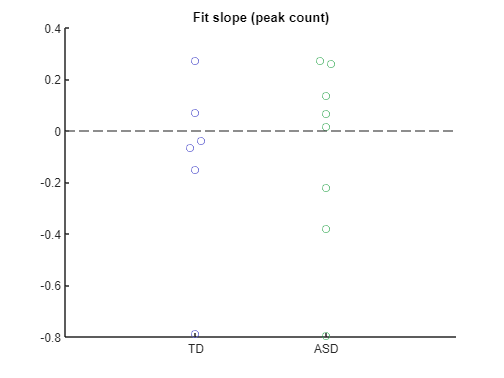

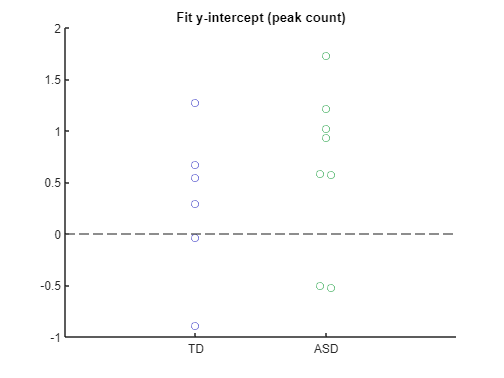

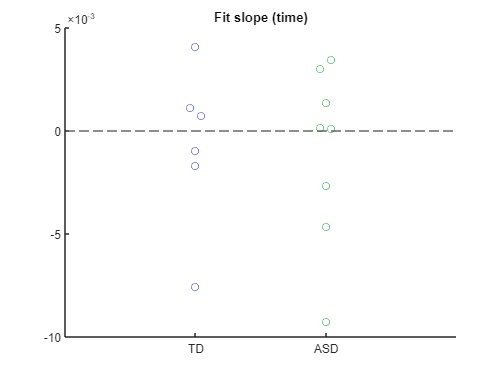

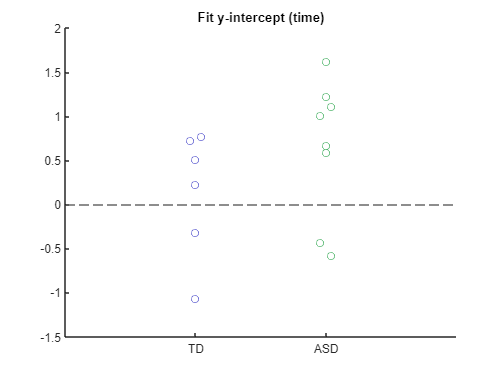

%method_name = get_method_plot_name(method);

% iterate through group
n_grps = length(groups); 
n_rois = length(rois);
n_erps = length(erps);
for i_r = 1:n_rois
    roi = rois{i_r};

    % plot individual erps
    f      = figure('Position',[50 50 1200 500]);
    ax     = zeros(n_grps);
    slopes = [];
    for i_g = 1:n_grps
        grp    = groups{i_g};
        subjs  = fieldnames(data.(grp).(roi));
        n_subj = length(subjs);
        subplot(1,n_grps,i_g), hold on
        for i_s = 1:n_subj
            subj = subjs{i_s};
            subj_data = data.(grp).(roi).(subj);
            subj_fit_pk_ct = polyfit(1:n_erps,subj_data,1);
            subj_fit_time  = polyfit(erp_times,subj_data,1);

            % add subject row to struct
            slopes(end+1).id  = str2double(subj(2:end));
            slopes(end).group = i_g;
            slopes(end).m_pk_ct = subj_fit_pk_ct(1);
            slopes(end).b_pk_ct = subj_fit_pk_ct(2);
            slopes(end).m_time  = subj_fit_time(1);
            slopes(end).b_time  = subj_fit_time(2);
            plot(subj_data,'-o')
        end
        ax(i_g) = gca;
        title([roi ' Suppression - ' grp])
        xticks(1:length(erps)); 
        xticklabels(erps)
        ylabel('Suppression ratio'); yline([0 1],'--')
    end
    linkaxes(ax)

    % plot average SI slopes (by peak count)
    all_coeffs_pks  = [slopes.group; slopes.m_pk_ct; slopes.b_pk_ct]';
    grp_coeffs_pks  = cell(n_grps,1);
    all_coeffs_time = [slopes.group; slopes.m_time; slopes.b_time]';
    grp_coeffs_time = cell(n_grps,1);
    figure, hold on
    s = [];
    for i_g = 1:n_grps
        s(end+1) = subplot(n_grps,1,i_g); hold on
        % get group coefficients and average
        grp_coeffs_pks{i_g} = all_coeffs_pks(all_coeffs_pks(:,1) == i_g,2:3);
        grp_coeff_avg = nanmean(grp_coeffs_pks{i_g},1);
        % plot individuals from group
        grp_n = length(grp_coeffs_pks{i_g});
        for i_s = 1:grp_n
            plot(polyval(grp_coeffs_pks{i_g}(i_s,:),1:n_erps),'-o','LineWidth',1,'Color','#ccc')
        end
        % plot group average and add to legend
        plot(polyval(grp_coeff_avg,1:n_erps),'o-','LineWidth',2,'Color',colors{i_g})
        xticks(1:n_erps), xticklabels(erps), yline([0 1],'--')
        title([groups{i_g} ', n=' int2str(grp_n)])
    end
    linkaxes(s)
    sgtitle([roi ' SI across ERPs'])
    sgtitle([roi ' Habituation across ERPs'])
    % plot average SI slopes (by time)
    lgnd = {};
    figure, hold on
    for i_g = 1:n_grps
        subplot(n_grps,1,i_g), hold on
        % get group coefficients and average
        grp_coeffs_time{i_g} = all_coeffs_time(all_coeffs_time(:,1) == i_g,2:3);
        grp_coeff_avg = nanmean(grp_coeffs_time{i_g},1);
        % plot group average and add to legend
        plot(polyval(grp_coeff_avg,0:max(erp_times)),'-','LineWidth',2,'Color',colors{i_g})
%         lgnd{end+1} = groups{i_g};
        % plot individuals from group
        for i_s = 1:length(grp_coeffs_time{i_g})
            plot(polyval(grp_coeffs_time{i_g}(i_s,:),0:max(erp_times)),':','LineWidth',1,'Color',colors{i_g})
%             lgnd{end+1} = '';
        end
        title(groups{i_g})
    end
    yline([0 1],'--','DisplayName','')
%     legend(lgnd,'Location','southwest')
    sgtitle([roi ' SI across ERPs (Time)'])
    xticks(erp_times), xticklabels(erps)

    %% scatter plots of coefficients (by peak count)
    % plot slopes
    figure, hold on, title('Fit slope (peak count)')
    plotSpread(cellfun(@(x) x(:,1),grp_coeffs_pks,'UniformOutput',false),'distributionMarkers','o','distributionColors',colors)
    yline(0,'--')
    xticks(1:n_grps), xticklabels(groups)

    % plot y intercepts
    figure, hold on, title('Fit y-intercept (peak count)')
    plotSpread(cellfun(@(x) x(:,2),grp_coeffs_pks,'UniformOutput',false),'distributionMarkers','o','distributionColors',colors)
    yline(0,'--')
    xticks(1:n_grps), xticklabels(groups)

    %% scatter plots of coefficients (by time)
%     % plot slopes
    figure, hold on, title('Fit slope (time)')
    plotSpread(cellfun(@(x) x(:,1),grp_coeffs_time,'UniformOutput',false),'distributionMarkers','o','distributionColors',colors)
    yline(0,'--')
    xticks(1:n_grps), xticklabels(groups)

    % plot y intercepts
    figure, hold on, title('Fit y-intercept (time)')
    plotSpread(cellfun(@(x) x(:,2),grp_coeffs_time,'UniformOutput',false),'distributionMarkers','o','distributionColors',colors)
    yline(0,'--')
    xticks(1:n_grps), xticklabels(groups)
end